syms x y lambda

fy = 1/lambda * exp(-y/lambda)

$$fy = \frac{{\mathrm{e}}^{-\frac{y}{\lambda }}}{\lambda }$$

fx_y = 1/y

$$fx\_y = \frac{1}{y}$$

fxy = fx_y*fy

$$fxy = \frac{{\mathrm{e}}^{-\frac{y}{\lambda }}}{\lambda \,y}$$

fx = int(fxy, y, [x,inf])

$$fx = -\frac{\left(\lim_{y\to \infty }\text{expint}\left(\frac{y}{\lambda }\right)\right)-\text{expint}\left(\frac{x}{\lambda }\right)+\left(\lim_{y\to 0^{{}_{-}}}\text{expint}\left(\frac{y}{\lambda }\right)\right)-\left(\lim_{y\to 0^{{}_{+}}}\text{expint}\left(\frac{y}{\lambda }\right)\right)}{\lambda }$$

mu_x = int(x*fx, x, [0,inf])

$$mu\_x = \begin{array}{l} -\frac{\left(\lim_{x\to \infty }\frac{\lambda^{2}\,{\mathrm{e}}^{-\frac{x}{\lambda }}}{2}+\frac{x^{2}\,\left(\lim_{y\to 0^{{}_{-}}}\sigma_{1}\right)}{2}-\frac{x^{2}\,\left(\lim_{y\to 0^{{}_{+}}}\sigma_{1}\right)}{2}+\frac{x^{2}\,\left(\lim_{y\to \infty }\sigma_{1}\right)}{2}-\frac{x^{2}\,\text{expint}\left(\frac{x}{\lambda }\right)}{2}+\frac{x\,\lambda \,{\mathrm{e}}^{-\frac{x}{\lambda }}}{2}\right)-\frac{\lambda^{2}}{2}}{\lambda }\\ \mathrm{where}\\ \sigma_{1}=\text{expint}\left(\frac{y}{\lambda }\right) \end{array}$$


int(y/lambda*exp(-y/lambda), [0,inf])

$$ans = \left\{ \begin{array}{cl} 0 & \text{ if }\lambda =0\\ -\frac{\left(\lim_{y\to \infty }\lambda \,{\mathrm{e}}^{-\frac{y}{\lambda }}\,\left(y+\lambda \right)\right)-\lambda^{2}}{\lambda } & \text{ if }\lambda \neq 0\\ \lambda & \text{ if }0\leq \mathrm{real}\left(\lambda \right) \end{array}\right.$$


int(y^2/lambda*exp(-y/lambda), [0,inf])

$$ans = \left\{ \begin{array}{cl} 0 & \text{ if }\lambda =0\\ 2 & \text{ if }\lambda =1\\ \frac{2\,\lambda^{3}-\left(\lim_{y\to \infty }\lambda \,{\mathrm{e}}^{-\frac{y}{\lambda }}\,\left(y\,\lambda \,2+y^{2}+2\,\lambda^{2}\right)\right)}{\lambda } & \text{ if }\lambda \neq 0\\ 2\,\lambda^{2} & \text{ if }0\leq \mathrm{real}\left(\lambda \right) \end{array}\right.$$

1/12*int(y^2*fy, [0,inf])

$$ans = \left\{ \begin{array}{cl} 0 & \text{ if }\lambda =0\\ \frac{1}{6} & \text{ if }\lambda =1\\ \frac{2\,\lambda^{3}-\left(\lim_{y\to \infty }\lambda \,{\mathrm{e}}^{-\frac{y}{\lambda }}\,\left(y\,\lambda \,2+y^{2}+2\,\lambda^{2}\right)\right)}{\lambda \,12} & \text{ if }\lambda \neq 0\\ \frac{\lambda^{2}}{6} & \text{ if }0\leq \mathrm{real}\left(\lambda \right) \end{array}\right.$$

int((y/2-lambda/2)^2*fy, [0,inf])

$$ans = \left\{ \begin{array}{cl} 0 & \text{ if }\lambda =0\\ -\frac{\frac{\lim_{y\to \infty }\lambda \,{\mathrm{e}}^{-\frac{y}{\lambda }}\,\left(y^{2}+\lambda^{2}\right)}{4}-\frac{\lambda^{3}}{4}}{\lambda } & \text{ if }\lambda \neq 0 \end{array}\right.$$

Problem 4

syms x v y
simplify((32+4*y-y^2)/(16-2*y))

$$ans = \frac{y}{2}+2$$

12 - ...
int((y/2)^2*y/12, [0,2]) - ...
int((y-1)^2*1/6, [2,6]) - ...
int((y/2+2)^2*(8-y)/12, [6,8])

$$ans = \frac{v}{6}-\frac{\left(v+1\right)\,\left(v^{2}+2\,v+2\right)}{24}+\frac{5\,v^{2}}{24}+\frac{v^{3}}{24}+\frac{13}{36}$$

5/18

ans = 0.2778

y = x+v

$$y = v+x$$

p = [1; y; y^2; y^3; y^4];

fx = 1/6;
fv = 1/2;
fxy = 1/12;

Rxp = int(fv * int(fx*x*p', x, [0, 6]), [0, 2])

$$Rxp = \left(\begin{array}{ccccc} 3 & 15 & 82 & \frac{2376}{5} & \frac{14352}{5} \end{array}\right)$$

Rp = int(fv * int(fx*p*p', x, [0, 6]), [0, 2])

$$Rp = \left(\begin{array}{ccccc} 1 & 4 & \frac{58}{3} & 104 & \frac{2992}{5}\\ 4 & \frac{58}{3} & 104 & \frac{2992}{5} & \frac{10816}{3}\\ \frac{58}{3} & 104 & \frac{2992}{5} & \frac{10816}{3} & \frac{157264}{7}\\ 104 & \frac{2992}{5} & \frac{10816}{3} & \frac{157264}{7} & 143680\\ \frac{2992}{5} & \frac{10816}{3} & \frac{157264}{7} & 143680 & \frac{42219776}{45} \end{array}\right)$$

Rx = int(fx*x*x',x, [0,6])

$$Rx = 12$$


M = Rxp*inv(Rp)

$$M = \left(\begin{array}{ccccc} \frac{513}{2393} & -\frac{27}{4786} & \frac{630}{2393} & -\frac{105}{4786} & 0 \end{array}\right)$$

M = eval(M)

M =     0.2144   -0.0056    0.2633   -0.0219         0


p = M*p

$$p = \frac{630\,{\left(v+x\right)}^{2}}{2393}-\frac{27\,x}{4786}-\frac{27\,v}{4786}-\frac{105\,{\left(v+x\right)}^{3}}{4786}+\frac{513}{2393}$$

error = Rx - M*Rxp'

$$error = \frac{1335}{4786}$$

error = eval(error)

error = 0.2789

y = linspace(0,8,100)

y =          0    0.0808    0.1616    0.2424    0.3232    0.4040    0.4848    0.5657    0.6465    0.7273    0.8081    0.8889    0.9697    1.0505    1.1313    1.2121    1.2929    1.3737    1.4545    1.5354    1.6162    1.6970    1.7778    1.8586    1.9394    2.0202    2.1010    2.1818    2.2626    2.3434    2.4242    2.5051    2.5859    2.6667    2.7475    2.8283    2.9091    2.9899    3.0707    3.1515    3.2323    3.3131    3.3939    3.4747    3.5556    3.6364    3.7172    3.7980    3.8788    3.9596



px = polyval(fliplr(M), y)

px =     0.2144    0.2156    0.2202    0.2282    0.2393    0.2536    0.2710    0.2915    0.3148    0.3411    0.3702    0.4020    0.4365    0.4735    0.5132    0.5553    0.5998    0.6466    0.6957    0.7469    0.8003    0.8557    0.9131    0.9725    1.0336    1.0965    1.1612    1.2274    1.2953    1.3646    1.4353    1.5074    1.5808    1.6554    1.7312    1.8080    1.8858    1.9646    2.0442    2.1247    2.2058    2.2877    2.3701    2.4530    2.5364    2.6202    2.7043    2.7886    2.8731    2.9577


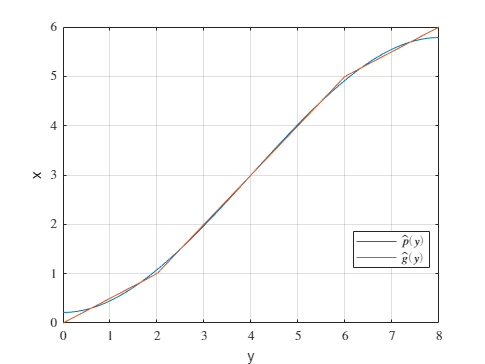


n = 100;
Exy = zeros(1,n);
for i = 1:n
    if y(i) <= 2
        Exy(i) = y(i)/2;
    elseif y(i) <= 6 && y(i) > 2
        Exy(i) = y(i) - 1;
    elseif y(i) <= 8 && y(i) > 6
        Exy(i) = y(i)/2 + 2;
    end
end

figure
plot(y,px)
hold on;
plot(y,Exy)
grid on
legend('$\hat{p}(y)$','$\hat{g}(y)$', 'Location','best')
xlabel('y')
ylabel('x')

y = 4

y = 4

v = 2*rand(1, 5000);
x = y - v;
mean_x = mean(x)

mean_x = 3.0085

## Problem 5

syms x y
int(int(x*y, y, [0,x^2]), [0,1])

$$ans = \frac{1}{12}$$

fxy = 12*x*y

$$fxy = 12\,x\,y$$


fy = int(fxy, x, [sqrt(y), 1])

$$fy = -6\,y\,\left(y-1\right)$$

fx_y = fxy/fy

$$fx\_y = -\frac{2\,x}{y-1}$$

g_y = int(x*fx_y, [sqrt(y), 1])

$$g\_y = \frac{6\,y^{3/2}-6}{9\,y-9}$$

fx = int(fxy, y, [0, x^2])

$$fx = 6\,x^{5}$$

Ex2 = int(x^2*fx, [0,1])

$$Ex2 = \frac{3}{4}$$

error1 = Ex2 - int(g_y^2*fy, [0, 1])

$$error1 = \frac{32\,\log\left(2\right)}{3}-\frac{443}{60}$$

eval(error1)

ans = 0.0102

p = [1; y; y^2; y^3];

Rxp = int(int(x*p'*fxy, y, [0, x^2]), [0, 1])

$$Rxp = \left(\begin{array}{cccc} \frac{6}{7} & \frac{4}{9} & \frac{3}{11} & \frac{12}{65} \end{array}\right)$$

Rp = int(int(p*p'*fxy, y, [0, x^2]), [0, 1])

$$Rp = \left(\begin{array}{cccc} 1 & \frac{1}{2} & \frac{3}{10} & \frac{1}{5}\\ \frac{1}{2} & \frac{3}{10} & \frac{1}{5} & \frac{1}{7}\\ \frac{3}{10} & \frac{1}{5} & \frac{1}{7} & \frac{3}{28}\\ \frac{1}{5} & \frac{1}{7} & \frac{3}{28} & \frac{1}{12} \end{array}\right)$$

Rx = Ex2

$$Rx = \frac{3}{4}$$


M = Rxp*inv(Rp)

$$M = \left(\begin{array}{cccc} \frac{6056}{9009} & \frac{608}{1287} & -\frac{292}{1287} & \frac{12}{143} \end{array}\right)$$

M = eval(M)

M =     0.6722    0.4724   -0.2269    0.0839


p = M*p

$$p = \frac{12\,y^{3}}{143}-\frac{292\,y^{2}}{1287}+\frac{608\,y}{1287}+\frac{6056}{9009}$$

error = Rx - M*Rxp'

$$error = \frac{16616671}{1623241620}$$

error = eval(error)

error = 0.0102

y = linspace(0,1,100)

y =          0    0.0101    0.0202    0.0303    0.0404    0.0505    0.0606    0.0707    0.0808    0.0909    0.1010    0.1111    0.1212    0.1313    0.1414    0.1515    0.1616    0.1717    0.1818    0.1919    0.2020    0.2121    0.2222    0.2323    0.2424    0.2525    0.2626    0.2727    0.2828    0.2929    0.3030    0.3131    0.3232    0.3333    0.3434    0.3535    0.3636    0.3737    0.3838    0.3939    0.4040    0.4141    0.4242    0.4343    0.4444    0.4545    0.4646    0.4747    0.4848    0.4949



px = polyval(fliplr(M), y)

px =     0.6722    0.6770    0.6817    0.6863    0.6909    0.6955    0.7000    0.7045    0.7090    0.7134    0.7177    0.7220    0.7263    0.7305    0.7347    0.7389    0.7430    0.7471    0.7511    0.7551    0.7591    0.7630    0.7669    0.7708    0.7746    0.7784    0.7822    0.7859    0.7896    0.7932    0.7969    0.8005    0.8040    0.8076    0.8111    0.8146    0.8180    0.8215    0.8249    0.8282    0.8316    0.8349    0.8382    0.8415    0.8447    0.8480    0.8512    0.8543    0.8575    0.8606



n = 100;
gx = (6*y.^1.5-6)./(9*y-9)

gx =     0.6667    0.6728    0.6785    0.6839    0.6891    0.6942    0.6991    0.7039    0.7086    0.7132    0.7178    0.7222    0.7266    0.7309    0.7352    0.7394    0.7435    0.7476    0.7516    0.7556    0.7596    0.7635    0.7674    0.7712    0.7750    0.7787    0.7824    0.7861    0.7898    0.7934    0.7970    0.8005    0.8040    0.8075    0.8110    0.8145    0.8179    0.8213    0.8247    0.8280    0.8313    0.8347    0.8379    0.8412    0.8444    0.8477    0.8509    0.8541    0.8572    0.8604


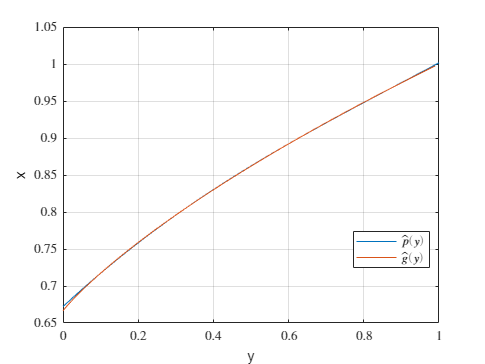


figure
plot(y,px)
hold on;
plot(y,gx)
grid on
legend('$\hat{p}(y)$','$\hat{g}(y)$', 'Location','best')
xlabel('y')
ylabel('x')

## Problem 7

syms x y gamma
fxy = gamma*exp(-x/(2*y+1))

$$fxy = \gamma \,{\mathrm{e}}^{-\frac{x}{2\,y+1}}$$

int(int(fxy, x, [0, inf]), y, [0,1])

$$ans = 2\,\gamma$$


fxy = 1/2*exp(-x/(2*y+1))

$$fxy = \frac{{\mathrm{e}}^{-\frac{x}{2\,y+1}}}{2}$$

fy = y+1/2

$$fy = y+\frac{1}{2}$$

fx_y = fxy/fy

$$fx\_y = \frac{{\mathrm{e}}^{-\frac{x}{2\,y+1}}}{2\,\left(y+\frac{1}{2}\right)}$$

g_y = int(x*fx_y, x, [0, inf])

$$g\_y = \begin{array}{l} \left\{ \begin{array}{cl} 0 & \text{ if }y=-\frac{1}{2}\\ -\frac{\left(\lim_{x\to \infty }{\mathrm{e}}^{-\frac{x}{2\,y+1}}\,\left(2\,y+1\right)\,\left(x+2\,y+1\right)\right)-\sigma_{1}}{\left(y+\frac{1}{2}\right)\,2} & \text{ if }y\neq -\frac{1}{2}\\ \frac{\sigma_{1}}{2\,\left(y+\frac{1}{2}\right)} & \text{ if }0\leq \mathrm{real}\left(2\,y+1\right) \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}={\left(2\,y+1\right)}^{2} \end{array}$$

p = [1;y];
Rxp = int(int(x*p'*fxy, x, [0, inf]), [0,1])

$$Rxp = \left(\begin{array}{cc} \frac{13}{6} & \frac{17}{12} \end{array}\right)$$

Rp = int(int(p*p'*fxy, x, [0,inf]), [0,1])

$$Rp = \left(\begin{array}{cc} 1 & \frac{7}{12}\\ \frac{7}{12} & \frac{5}{12} \end{array}\right)$$

fx = int(fxy, y, [0,1])

$$fx = \frac{3\,{\mathrm{e}}^{-\frac{x}{3}}}{4}-\frac{{\mathrm{e}}^{-x}}{4}-\frac{x\,\text{ei}\left(-x\right)}{4}+\frac{x\,\text{ei}\left(-\frac{x}{3}\right)}{4}$$

Rx = int(x^2*fx, [0, inf])

$$Rx = 10$$

M = Rxp*inv(Rp)

$$M = \left(\begin{array}{cc} 1 & 2 \end{array}\right)$$

M = eval(M)

M =      1     2


p = M*p

$$p = 2\,y+1$$

error = Rx-M*Rxp'

$$error = 5$$

error = eval(error)

error = 5